# Vigas Curvas

## Ejercicio teórico 1

Determinar el CS del gancho del croquis para una carga máxima de 60000 [N].

Comparar resultado con lo obtenido con viga recta.

- Determinar las propiedades de la sección del gancho.

De la Tabla 2, CASO 3, se tiene:


$$A = \frac{b_1+b_2}{2}(c+a)
$$



$$A_m=\frac{b_1 \cdot c -b_2 \cdot a}{c-a} \ln \frac{c}{a}-b_1-b_2$$



$$R = \frac{a(2b_1+b_2)+c(b_1+2b_2)}{3(b_1+b_2)}$$


b_1 = 80; b_2 = 20; a = 60;c = 180;
A = (b_1+b_2)/2 *(c-a)

A = 6000

A_m =(b_1* c -b_2* a)/(c-a)*log(c/a)-b_1+b_2

A_m = 60.8474

R = (a*(2*b_1+b_2)+c*(b_1+2*b_2))/(3*(b_1+b_2))

R = 108

Con las propiedades calculadas podemos encontrar el momento máximo, que se aplica al eje neutro (R calculado).


$$\sigma_{\theta} = \frac{N}{A}-\frac{M_z}{R.A_m-A}\left(\frac{1}{r}-\frac{A_m}{A}\right)$$


Con r = 60:

N = 60000; Mz = N*R;r = 60;
S_theta = N/A+ Mz/(R*A_m-A)*(1/r-A_m/A)

S_theta = 83.9874

La tensión de fluencia del material es  280 MPa.

CS =280/S_theta

CS = 3.3338

## Ejercicio 3 del teórico

Determinar el coeficiente de seguridad de la prensa del croquis para una carga máxima de 120000 [N].

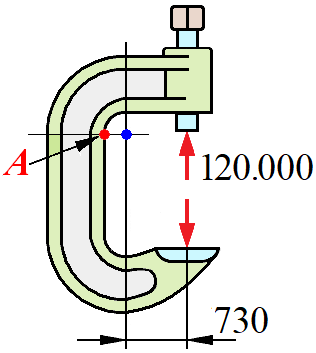 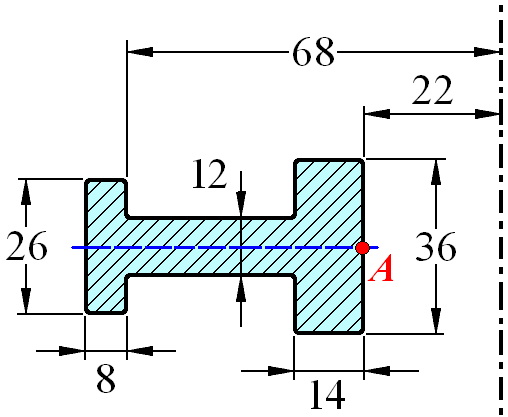

Para resolverlo hay que descomponerlo en secciones más fáciles de trabajar y además aplicar la corrección de Bleich. *(en complejidad es el segundo ejercicio)*

*Corrección de Bleich;*


$$b_1'=2 (\alpha_i \cdot l_i)+t$$
 


$$\sigma_z = - \beta \cdot \sigma_\theta$$


- Sección más alejada, corrección de Bleich

r_m = 68+4; 


$$\lambda = \frac{R\cdot t}{r_m^2\sqrt{1-\nu^2} }$$



$$\gamma=\frac{R}{r_m}$$
